clear
close all
clc

## load example multisubject FC matrices

adj = readNPY("adj_mus_dynamic.npy");
z = readNPY("z_mus_dynamic.npy");
B = permute(adj, [3,4,1,2]);
sizeB = size(B);
A = reshape(B, sizeB(1),sizeB(2),sizeB(3)*sizeB(4),1);

% load example_mats.mat
% A = A(:,:,1:5);

[N,~,T] = size(A);  % number of nodes/layers
C = cell(T,1);      % create cell array
for i = 1:T         % populate array
    C{i} = A(:,:,i); % i-th layer of A, 100*100
end

## set some parameters

gammarange = [double(min(A(:))), double(max(A(:)))]; % range of gamma values to consider
omegarange = [-0.5,1.5];            % range of omega values to consider
samplesPerStage = 50;              % number of samples per stage (ideally should be large) 250
nstage = 2;                         % number of stages (ideally should be large) 5
keep = 20;                          % number of nearest neighbors
couplingtype = 'categorical';       % nature of interlayer coupling (could also be ordered)

## get initial estimate of boundaries

stage = 1/2, sample = 25/50
stage = 1/2, sample = 50/50
stage = 2/2, sample = 25/50
stage = 2/2, sample = 50/50


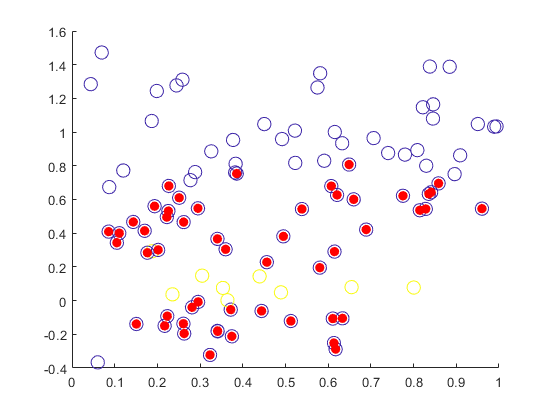

[gbound,obound,outputdata] = ...    % run boundary estimator
    fcn_get_bounds(C,gammarange,omegarange,samplesPerStage,nstage,keep,couplingtype);

## sample from within those boundaries

samplesTotal = 100;                % total number of samples
[S,G,O] = fcn_staged_multilayer(C,gbound,obound,samplesTotal,couplingtype);
% size(s) = number of nodes, number of layers (time*subject), number of
% samples

main_dir = "D:\OneDrive\OneDrive - UW-Madison\Sunduz\processed data\settingSSoS\n100-k2-p_in2btw25-p_out1btw1\";
% main_dir = "C:\OneDrive\OneDrive - UW-Madison\Sunduz\processed data\settingSSoS\n100-k2-p_in2btw25-p_out1btw1\"
data_dir = "r_time0-time_horizon2-r_subject0-num_subjects16\0\";

zS = load(main_dir+data_dir+"z_pred.mat").zS;
G = load(main_dir+data_dir+"G.mat").G;
O = load(main_dir+data_dir+"O.mat").O;
ari = load(main_dir+data_dir+"aris.mat").aris;

sizeS = size(zS);
sS = reshape(zS, sizeS(1)*sizeS(2), sizeS(3), sizeS(4));
S = permute(sS, [2,1,3]);

% B = permute(adj, [3,4,1,2]);
% sizeB = size(B);
% A = reshape(B, sizeB(1),sizeB(2),sizeB(3)*sizeB(4),1);

## calculate flexibility

switch couplingtype
    case 'categorical'
        [~,flx] = fcn_fastflx(S);
        flx = squeeze(nanmean(nanmean(flx,2),3));
    case 'ordered'
        flx = squeeze(nanmean(S(:,1:end - 1,:) ~= S(:,2:end,:),2));
end

## calculate node entropy and nonsingleton communities

ent = zeros(N,samplesTotal);        % preallocate array for entropy
nonsingle = zeros(samplesTotal,1);  % preallocate array for nonsingletons
for isample = 1:samplesTotal
    mx = max(max(S(:,:,isample)));  % max communities per sample
    bins = 1:mx;                    % bins
    h = hist(S(:,:,isample)',bins); % node histogram
    p = bsxfun(@rdivide,h,sum(h));  % probabilities
    e = -nansum(p.*log2(p));        % entropy
    ent(:,isample) = e;             % store
    h = hist(S(:,:,isample),bins);  % layer histogram
    nonsingle(isample,:) = ...      % number of nonsingletons
        nanmean(sum(h > 1));
end

## make some figures

sz = 10;                            % size of points
f = fcn_rickplot([2,2,9,3]);        % create figure
vals = ...                          % concatenate variables
    [nanmean(ent)',squeeze(mean(max(S))),nonsingle];
% [entropy, average # (over layers) of clusters of each sample, nonsingletons] 
for i = 1:3
    ax = axes('outerposition',[(i - 1)/3,0,1/3,1]);
    scatter(G,O,sz,vals(:,i),'filled');
end

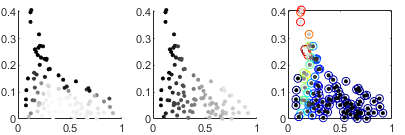

max_color_value = size(ari);
max_color_value = max_color_value(3);
cm = colormap(gray(max_color_value));

mm_ari = squeeze(mean(mean(ari)));
col = ceil(mm_ari*max_color_value);

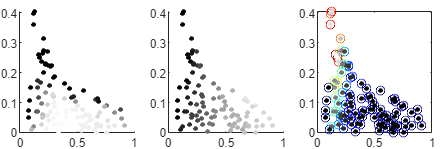

scatter(G,O,sz, col,"filled");

for i = 1:1:max_color_value
    selected_color = cm(col(i),:);
    plot(G(i),O(i),".","color",selected_color);
    hold on;
end

## if you use this code, please cite: